# Load Matlab datafile

clear all;
%load(fullfile('ECG.mat'));
%load(fullfile('ECGNEW2.mat'));
load(fullfile('ECGNEW.mat'));
%load(fullfile('PPG.mat'));
%load(fullfile('GSR.mat'));
%load(fullfile('ECGPPG.mat'));
%load(fullfile('ECGGSR.mat'));
%Data = importdata('TT2.csv');
%Data = importdata('ECGACC.csv');
%TrainTestData = Data.Data;
%train_n_test_label = Data.Labels;
TrainTestData = ECGNew.Data;
train_n_test_label = ECGNew.Labels;
%TrainTestData=[TrainD(2:end),TestD(2:end)]
%train_n_test_label=[TrainD(1:), TestD(1:)]



## Split data into testing and training set

%trainData1 = TrainTestData(:,1:45000);
%testData1 = TrainTestData(:,45001:65536);
%trainData1 = TrainTestData(:,1:8000);
%testData1 = TrainTestData(:,8001:16000);
DataSegment1 = TrainTestData(:,1:8000);
DataSegment2 = TrainTestData(:,8001:16000);
DataSegment3 = TrainTestData(:,16001:24000);
DataSegment4 = TrainTestData(:,24001:32000);
DataSegment5 = TrainTestData(:,32001:40000);
DataSegment6 = TrainTestData(:,40001:48000);
DataSegment7 = TrainTestData(:,48001:56000);
%FinalDataSegment=DataSegment1+DataSegment3+DataSegment4+DataSegment5+DataSegment6+DataSegment7;  
FinalDataSegment=vertcat(DataSegment1(1:53,:),DataSegment2(1:53,:),DataSegment3(1:53,:),DataSegment4(1:53,:),DataSegment5(1:53,:),DataSegment6(1:53,:),DataSegment7(1:53,:));
train_n_test_label=vertcat(train_n_test_label(:),train_n_test_label(:),train_n_test_label(:),train_n_test_label(:),train_n_test_label(:),train_n_test_label(:),train_n_test_label(:));
trainData1 = FinalDataSegment(:,1:4000);
testData1 = FinalDataSegment(:,4001:8000);

## Feature extraction

%timeWindow = 8192;
timeWindow = 4000; % for ECGPPG, GSR
%timeWindow = 8192; % for ECGPPG, GSR
%timeWindow = 400; %For other signals
%timeWindow = 1000;
AROrder = 4;

transformLevel = 2;
%transformLevel = 5;
%[trainFeatures,testFeatures,featureindices] = featureExtraction(trainData,testData,timeWindow,AROrder,transformLevel);
[trainFeatures,testFeatures,featureindices] = featureExtraction(trainData1,testData1,timeWindow,AROrder,transformLevel);



allFeatures = [trainFeatures;testFeatures];
allLabels = [train_n_test_label;train_n_test_label];

%allLabels = [train_n_test_labelCopy;train_n_test_labelCopy];
%{
figure
boxplot(allFeatures(:,featureindices.entropyFeatures(1)),allLabels,'notch','on')
boxplot(allFeatures(:,featureindices.entropyFeatures(2)),allLabels,'notch','on')
plot(allFeatures(:,featureindices.entropyFeatures(1)))
ylabel('Entropy')
xlabel('Signal Data')
title('Feature Extraction')

plot(allFeatures(:,featureindices.ARFeatures(1)))
ylabel('AR Coefficient')
xlabel('Signal Data')
title('Feature Extraction')
figure
boxplot(allFeatures(:,featureindices.ARFeatures(1)),allLabels,'notch','on')
ylabel('Holder Exponent Range')
title('Range of Singularity Spectrum by Group (First Time Window)')
grid on
%}
%{
plot(allFeatures(:,featureindices.varianceFeatures(70)))
ylabel('Wavelet Variance')
xlabel('Signal Data')
title('Feature Extraction')
boxplot(allFeatures(:,featureindices.varianceFeatures(1)),allLabels,'notch','on')
ylabel('Wavelet Variance')
title('Wavelet Variance by Group')
grid on

features = [trainFeatures; testFeatures];
%}

## Feature Selection

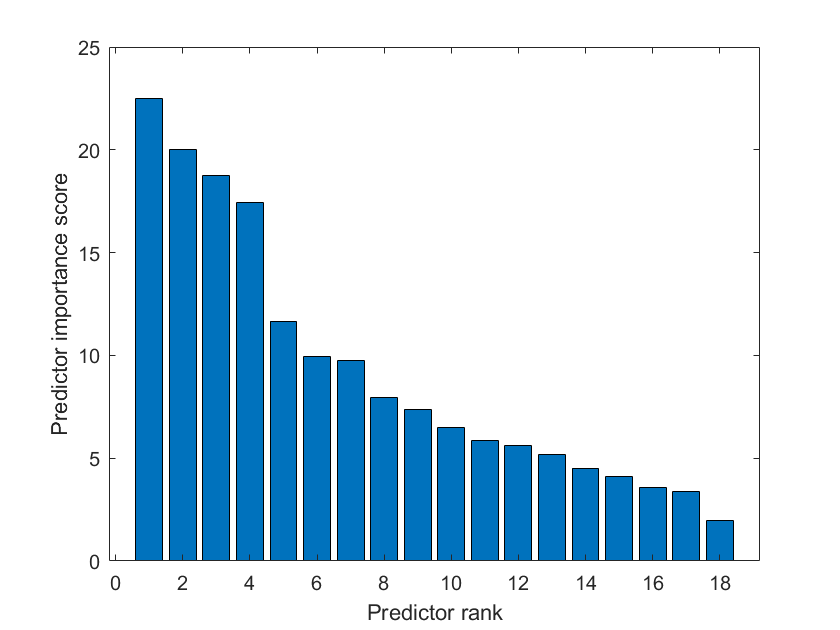


   [idx,scores] = fscchi2(trainFeatures,train_n_test_label);
   %[idx,scores] = fscmrmr(trainFeatures,train_n_test_label);
   %[idx,scores] = relieff(trainFeatures,train_n_test_label,12);
    bar(scores(idx))
    %idx=sort(idx);
    xlabel('Predictor rank')
    ylabel('Predictor importance score')

    
   selected_feature_indx =  idx(:,1:16); 
   
    % Plot feature weights
    %stem(mdl.FeatureWeights,'bo');
    bar(scores(idx))
    xlabel('Predictor rank')
    ylabel('Predictor importance score')

    
    % save for future reference
    save('SelectedFeatures', 'selected_feature_indx');

## classification

rng(1)
%{
template = templateSVM(...
    'KernelFunction','polynomial',...
   'KernelScale','auto',...
    'BoxConstraint',1,...
    'Standardize',true);
% testing with rbf
%template = templateSVM(...
   % 'KernelFunction','rbf',...
   % 'KernelScale','auto',...
   % 'BoxConstraint',1,...
   % 'Standardize',true);

% model = fitcecoc(...
%      trainFeatures,...
%      trainLabel,...
%      'Learners',template,...
%      'Coding','onevsone',...
%      'ClassNames',{'AUTH','NAUTH'});

model = fitcecoc(...
     trainFeatures,...
     train_n_test_label,...
     'Learners',template,...
     'Coding','onevsone', ...
     'ClassNames',{'AUTH','NAUTH'});
%}
%predEn = predict(modelEN,testFeatures);
%predKNN=predict(modelKNN,testFeatures);
%model = fitcensemble(trainFeatures(:,selected_feature_indx),train_n_test_label);
%model = fitcknn(trainFeatures(:,selected_feature_indx),train_n_test_label);
model=fitcgam(trainFeatures(:,selected_feature_indx),... 
train_n_test_label);  
predLabels = predict(model,testFeatures(:,selected_feature_indx));

[label,score]=predict(model,testFeatures(:,selected_feature_indx));
classOrder = model.ClassNames

classOrder = 2×1 cell array
    {'AUTH' }
    {'NAUTH'}


kfoldmodel = crossval(model,'KFold',5);
classLabels = kfoldPredict(kfoldmodel);
loss = kfoldLoss(kfoldmodel)

loss = 0.0458

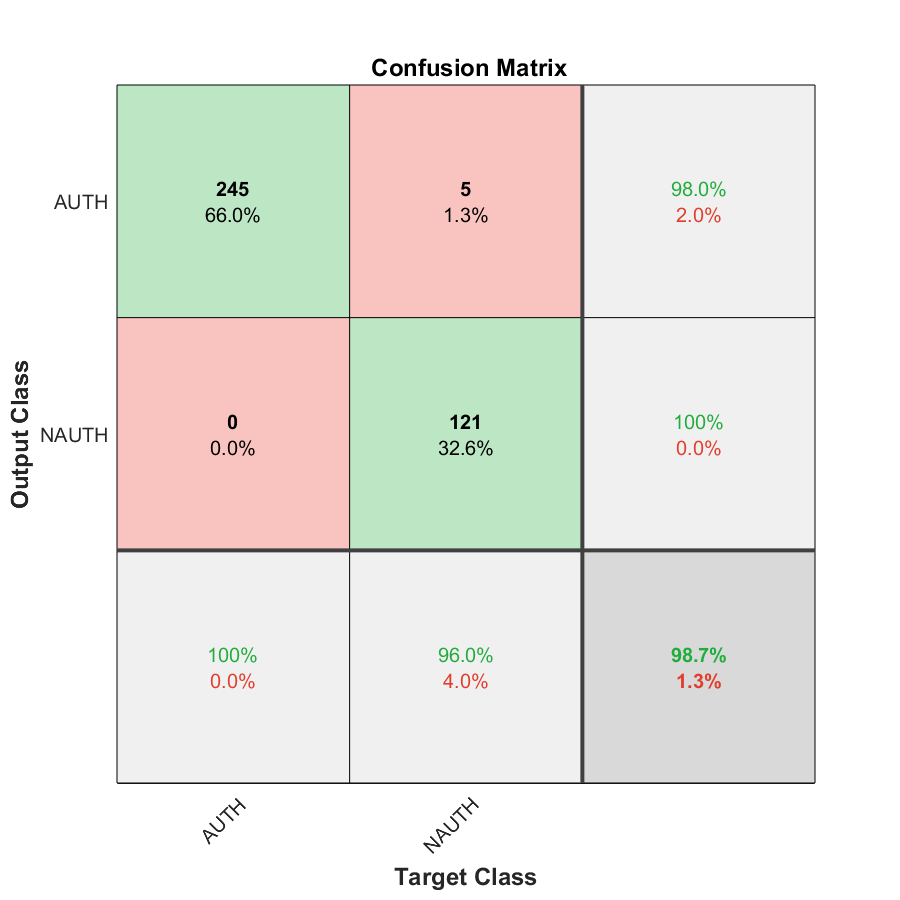

%correctPredictions = strcmp(predLabels,testLabel);
correctPredictions = strcmp(predLabels,train_n_test_label);
[confusionMatrix] = confusionmat(train_n_test_label,predLabels);
plotconfusion(categorical(train_n_test_label),categorical(predLabels));

%mdlSVM = fitcsvm(testFeatures,predLabels,'Standardize',true);
%mdlSVM = fitPosterior(mdlSVM);


## calculate prediction results

truePositive = confusionMatrix(1,1);
falsePositive = sum(confusionMatrix(:,1)) - confusionMatrix(1,1);
falseNegative = sum(confusionMatrix(1,:)) - confusionMatrix(1,1);
trueNegative = confusionMatrix(2,2);

precision = truePositive / (truePositive + falsePositive);
recall = truePositive / (truePositive + falseNegative);
trueNegativeRate = trueNegative / (trueNegative+falsePositive);
falseNegativeRate = falseNegative / (falseNegative+truePositive);
falsePositiveRate= 1 - trueNegativeRate;
truePositiveRate= truePositive/(truePositive + falseNegative);
f1 = 2 * precision * recall / (precision + recall);
EER=(falsePositive+falseNegative) / (truePositive+falsePositive+falsePositive+trueNegative);

## display result

%testAccuracy = sum(correctPredictions) / length(testLabel)*100
testAccuracy = sum(correctPredictions) / length(train_n_test_label)*100

testAccuracy = 98.6523


confusionMatrixTable = array2table([truePositive falsePositive;...
    falseNegative trueNegative],'VariableNames',{'Positive','Negative'},'RowNames',...
    {'Positive','Negative'});

resultTable = array2table([precision recall f1 trueNegativeRate ...
    falseNegativeRate falsePositiveRate],'VariableNames',{'Precision','Recall','F1_Score',...
    'True Negative Rate', 'False Negative Rate', 'False Positive Rate' },'RowNames',...
    {'value',});

disp(confusionMatrixTable);

                Positive    Negative
                ________    ________

    Positive      245           5   
    Negative        0         121   



disp(resultTable);

             Precision    Recall    F1_Score    True Negative Rate    False Negative Rate    False Positive Rate
             _________    ______    ________    __________________    ___________________    ___________________

    value      0.98         1        0.9899          0.96032                   0                  0.039683      



AUC Curve


[Xsvm,Ysvm,Tsvm,AUCsvm] = perfcurve(predLabels,score(:,1),'AUTH');
[Xsvm1,Ysvm2,Tsvm2,AUCsvm2] = perfcurve(predLabels,score(:,2),'NAUTH');
%plot(Xsvm,Ysvm)
%xlabel('False positive rate') 
%ylabel('True positive rate')
%title('ROC for Classification')

